load('S01.mat')


trigger=data{1,1}.trial %start and stop signal 

trigger = 12×1 uint32 column vector
    238
    360
    639
    760
   1039
   1160
   1439
   1560
   1839
   1960


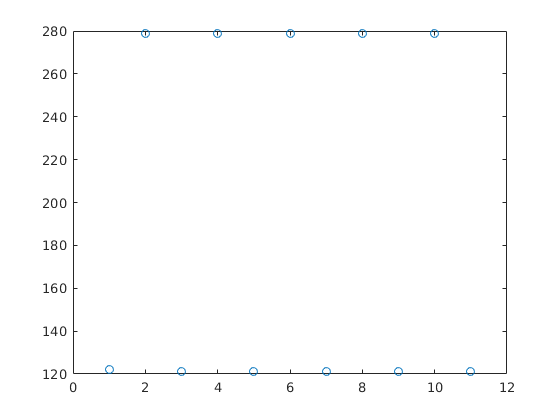

plot(diff(trigger),"o")

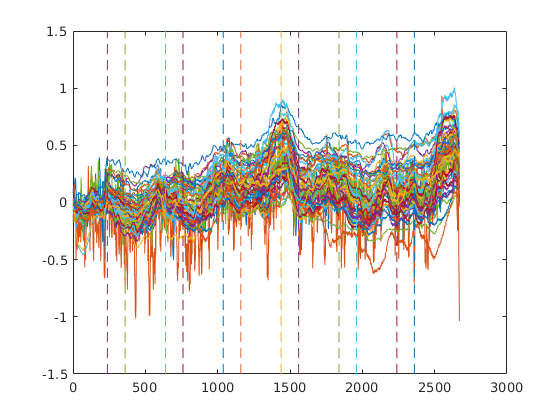

oxy=data{1,1}.X(:,1:52);
plot(oxy)
hold on
for l=trigger
    plot([l,l],[-1.5,1.5],"--")
end
hold off

Compute cusum

N=length(oxy(:,1))

N = 2671

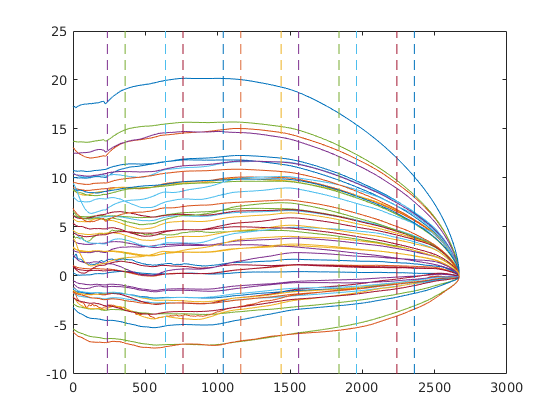

cusum_2nd=flipud(cumsum(flipud(oxy)));
t1=1:N-1;
cusum_1st=sqrt((N-1-t1)./((N-1)*t1))'.*cumsum(oxy(1:end-1,:));
t2=1:N-1;
cusum_2nd=cusum_2nd(2:end,:)*sqrt(t2/((N-t2)*N));
cusum=cusum_1st+cusum_2nd;
figure()
plot(cusum)


hold on
for l=trigger
    plot([l,l],[-10,25],"--")% it is the plot of vertical lines
end
hold off

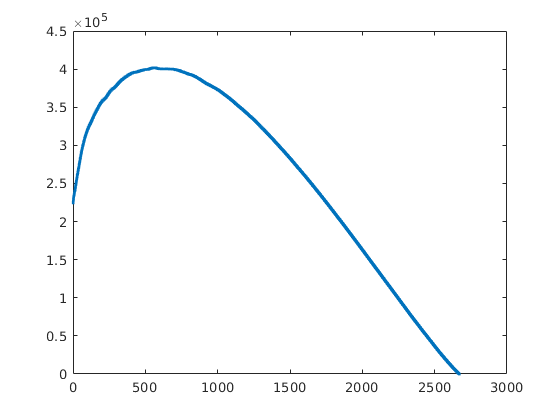

plot(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'),".")

[M,k]=max(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'))

M = 4.0171e+05

k = 563

[cusum, idx]=my_cusum(oxy);

N =         2671


M =    4.0171e+05


k =    563


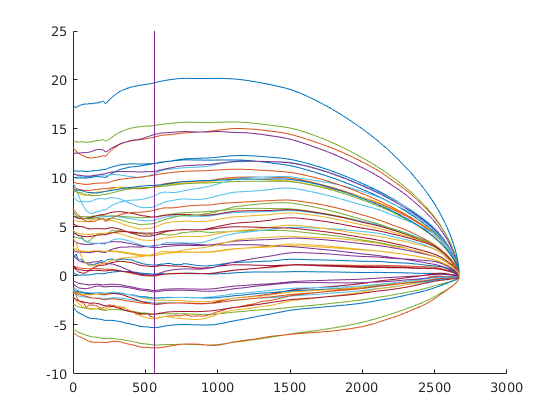

figure()
hold on
plot(cusum)
plot([idx,idx],[-10 25])
hold off

Select the region of interest

roi1=[46,47,48]

roi1 =     46    47    48


roi2=[18,28,29]

roi2 =     18    28    29


roi3=[13, 23, 24]

roi3 =     13    23    24


N = 360

cusum =    -0.0720   -0.0707   -0.0605   -0.0338   -0.0479   -0.0046   -0.0350   -0.0307   -0.0607
   -1.6872   -1.2429   -0.6329   -0.2948    0.2415    0.6770   -0.3014   -0.1426   -0.8195
   -1.7066   -1.2611   -0.6494   -0.3039    0.2281    0.6763   -0.3104   -0.1498   -0.8353
   -1.7247   -1.2784   -0.6669   -0.3133    0.2156    0.6742   -0.3187   -0.1567   -0.8506
   -1.7429   -1.2965   -0.6859   -0.3231    0.2030    0.6710   -0.3270   -0.1640   -0.8664
   -1.7618   -1.3155   -0.7059   -0.3333    0.1906    0.6671   -0.3353   -0.1715   -0.8827
   -1.7761   -1.3289   -0.7177   -0.3412    0.1811    0.6654   -0.3412   -0.1768   -0.8935
   -1.7868   -1.3383   -0.7240   -0.3470    0.1743    0.6650   -0.3460   -0.1804   -0.9003
   -1.7979   -1.3485   -0.7318   -0.3531    0.1674    0.6640   -0.3512   -0.1840   -0.9075
   -1.8089   -1.3585   -0.7396   -0.3591    0.1610    0.6627   -0.3565   -0.1872   -0.9139


idx = 83

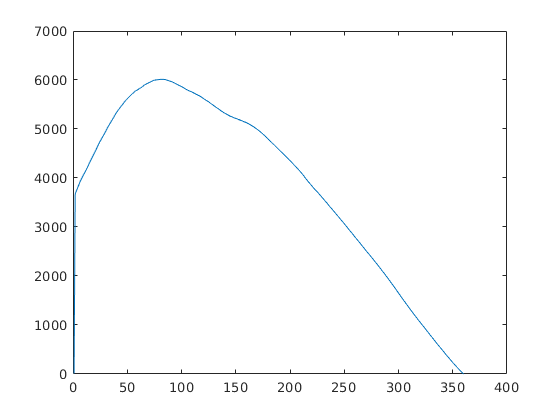

[cusum, idx]=cusum_padding(oxy(1:trigger(2),[roi1 roi2 roi3]))

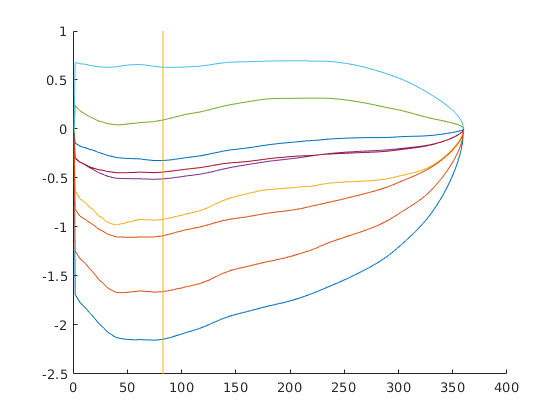

figure()
hold on
plot(cusum)
plot([idx,idx],[-2.5 1])
hold off